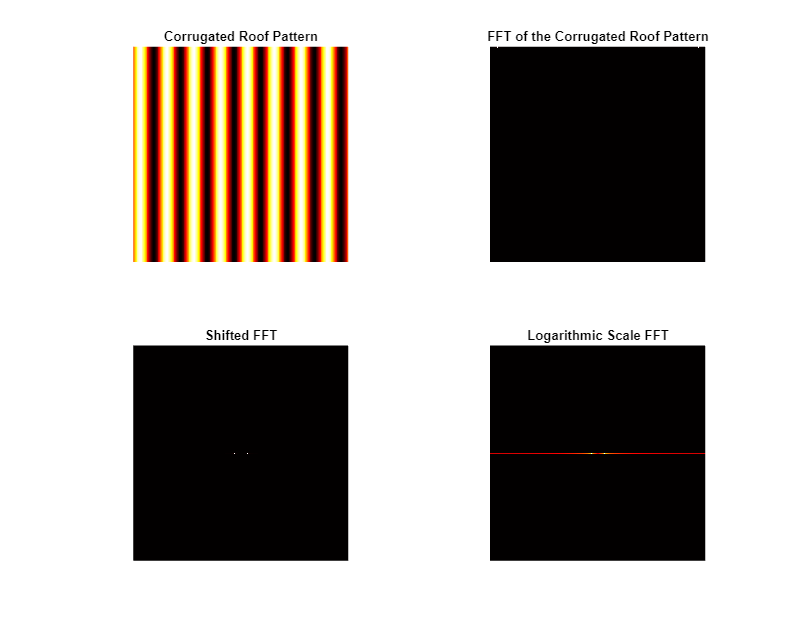

% ACTIVITY 2.2.1 ROTATION PROPERTY OF THE FT
% corrugated roof pattern
N = 256; 
f = 4;
amplitude = 1;

x = linspace(-1, 1, N);
y = linspace(-1, 1, N);
[X, Y] = meshgrid(x, y);
Z = amplitude * sin(2*pi*f*X);

% FFT of the rotated sinusoid
fft_result = fft2(Z);
fft_shifted = fftshift(fft_result);
fft_shifted_log = log(abs(fft_shifted) + 1);

% Rescale the logarithmic scale FFT to the range [0, 1]
fft_shifted_log = rescale(fft_shifted_log, 'InputMin', min(fft_shifted_log(:)), 'InputMax', max(fft_shifted_log(:)));

%Plotting
figure('Position', [200, 100, 900, 700]);
subplot(2, 2, 1); imshow(Z, []); title('Corrugated Roof Pattern');
subplot(2, 2, 2); imagesc(abs(fft_result)); axis square; title('FFT of the Corrugated Roof Pattern'); axis off;
subplot(2, 2, 3); imagesc(abs(fft_shifted)); axis square; title('Shifted FFT'); axis off;
subplot(2, 2, 4); imagesc(fft_shifted_log); axis square; title('Logarithmic Scale FFT'); axis off;
colormap hot;

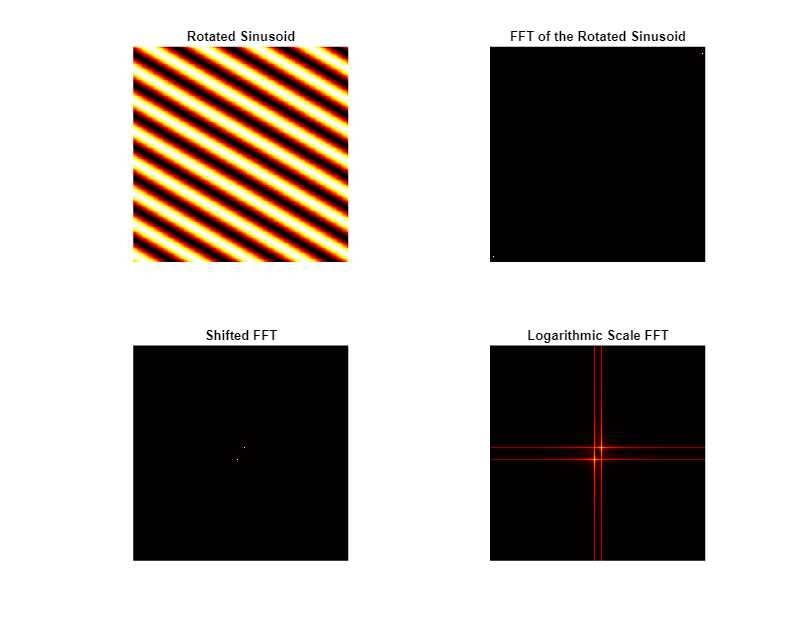

% Rotated sinusoid
N = 256;
f = 4;
theta = 30;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
rotated_sinusoid = sin(2*pi*f*(Y*cosd(theta) - X*sind(theta)));

% FFT of the rotated sinusoid
fft_result = fft2(rotated_sinusoid);
fft_shifted = fftshift(fft_result);
fft_shifted_log = log(abs(fft_shifted) + 1);

% Rescale the logarithmic scale FFT to the range [0, 1]
fft_shifted_log = rescale(fft_shifted_log, 'InputMin', min(fft_shifted_log(:)), 'InputMax', max(fft_shifted_log(:)));

%Plotting
figure('Position', [200, 100, 900, 700]);
subplot(2, 2, 1); imshow(rotated_sinusoid, []); title('Rotated Sinusoid');
subplot(2, 2, 2); imagesc(abs(fft_result));axis square; title('FFT of the Rotated Sinusoid'); axis off;
subplot(2, 2, 3); imagesc(abs(fft_shifted)); axis square; title('Shifted FFT'); axis off;
subplot(2, 2, 4); imagesc(abs(fft_shifted_log));axis square; title('Logarithmic Scale FFT'); axis off;
colormap hot;

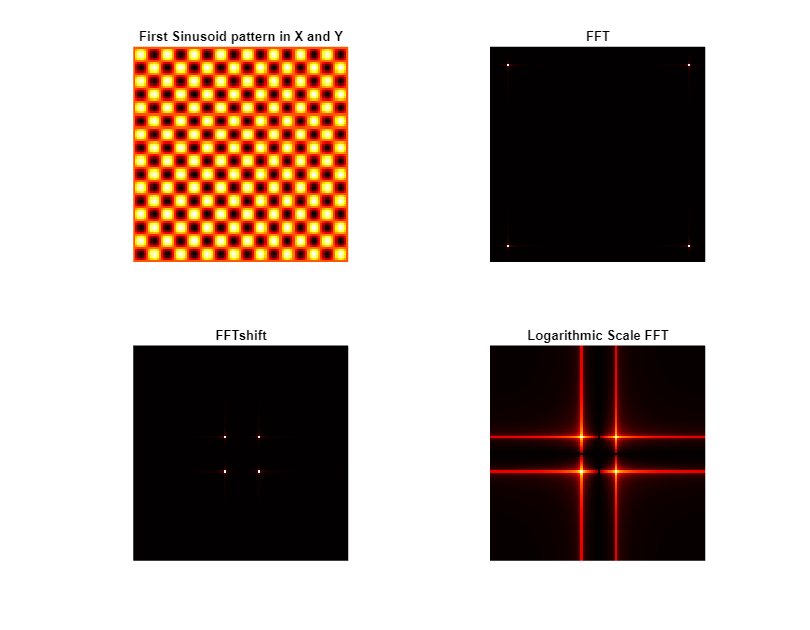

%Combination of sinusoids in X and Y pattern 1
nx = 100;
ny = 100;
x = linspace(-1, 1, nx);
y = linspace(-1, 1, ny);
[X, Y] = meshgrid(x, y);
f = 4;
Z = sin(2*pi*f*X) .* sin(2*pi*f*Y);

%FFT of the pattern
Z_fft = fft2(Z);
Z_fftshift = fftshift(Z_fft);
Z_fft_log = log(abs(Z_fftshift) + 1);

%Plotting
figure('Position', [200, 100, 900, 700]);
subplot(2, 2, 1);imagesc(Z); axis image; title('First Sinusoid pattern in X and Y'); axis off;
subplot(2, 2, 2); imagesc(abs(Z_fft)); axis image; title('FFT'); axis off;
subplot(2, 2, 3); imagesc(abs(Z_fftshift)); axis image; title('FFTshift'); axis off;
subplot(2, 2, 4); imagesc(Z_fft_log); axis image;title('Logarithmic Scale FFT'); axis off;
colormap hot;

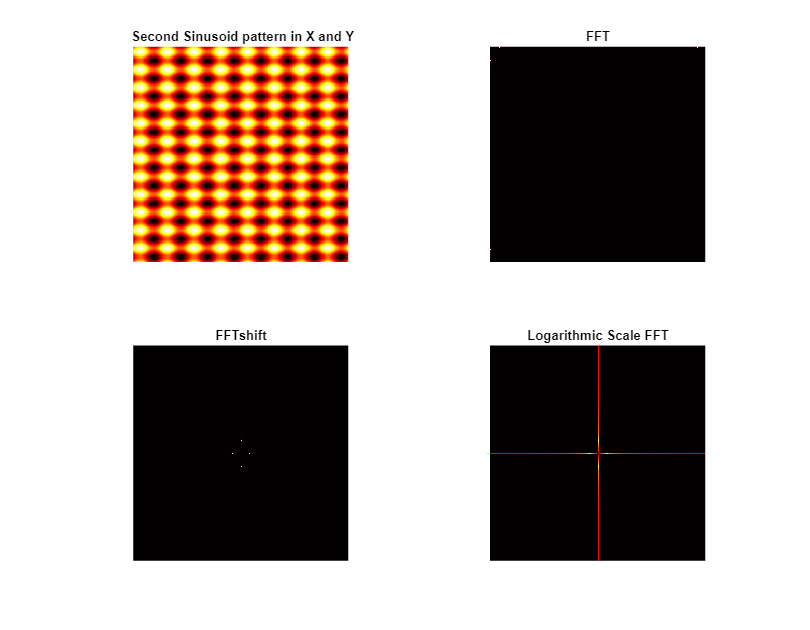

%Combination of sinusoids in X and Y pattern 2
nx = 200;
ny = 200;
x = linspace(-1, 1, nx);
y = linspace(-1, 1, ny);
[X, Y] = meshgrid(x, y);
f1 = 4;
f2 = 6;
Z = sin(2*pi*f1*X) + sin(2*pi*f2*Y);

%FFT of the pattern
Z_fft = fft2(Z);
Z_fftshift = fftshift(Z_fft);
Z_fftshift_log = log(abs(Z_fftshift) + 1);

%Plotting
figure('Position', [200, 100, 900, 700]);
subplot(2, 2, 1); imshow(Z, []); title(' Second Sinusoid pattern in X and Y');
subplot(2, 2, 2); imagesc(abs(Z_fft)); axis square; title('FFT'); axis off;
subplot(2, 2, 3); imagesc(abs(Z_fftshift)); axis square; title('FFTshift'); axis off;
subplot(2, 2, 4); imagesc(Z_fftshift_log); axis square; title('Logarithmic Scale FFT'); axis off;
colormap hot;

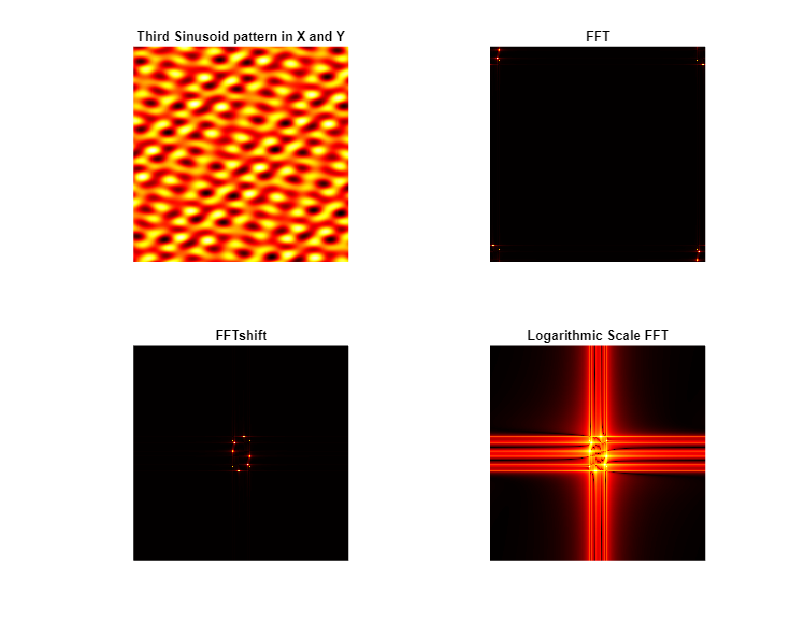

%Combination of sinusoids in X and Y pattern 3
% Define parameters
nx = 200;
ny = 200;
x = linspace(-1, 1, nx);
y = linspace(-1, 1, ny);
[X, Y] = meshgrid(x, y);
f1 = 4;
f2 = 6;
f3 = 8;
theta1 = 30;
theta2 = 45;
theta3 = 60;
Z = sin(2*pi*f1*X) .* sin(2*pi*f2*Y);
Z = Z + sin(2 * pi * f3 * (Y*sin(theta1) + X*cos(theta1)));
Z = Z + sin(2 * pi * f2 * (Y*sin(theta2) + X*cos(theta2)));
Z = Z + sin(2 * pi * f1 * (Y*sin(theta3) + X*cos(theta3)));

%FFT of the pattern
Z_fft = fft2(Z);
Z_fftshift = fftshift(Z_fft);
Z_fftshift_log = log(abs(Z_fftshift) + 1);

%plotting
figure('Position', [200, 100, 900, 700]);
subplot(2, 2, 1); imshow(Z, []); title('Third Sinusoid pattern in X and Y'); 
subplot(2, 2, 2); imagesc(abs(Z_fft)); axis square; title('FFT'); axis off;
subplot(2, 2, 3); imagesc(abs(Z_fftshift)); axis square; title('FFTshift'); axis off;
subplot(2, 2, 4); imagesc(Z_fftshift_log); axis square; title('Logarithmic Scale FFT'); axis off;
colormap hot;